#### **HomeWork n.1 2023/24**

### ***Beniamino Nardone ***0124002440

**Punto 1: Definite la function Matlab che implementa la vostra funzione di riferimento e che chiamerete **`funrif`


$$e^{-0.6x} \cdot \left(cos \left(\frac {p \cdot x}{2}\right)\right)^2 +  \frac {q}{1+3x^2}sin(\pi x)-2$$


Definisco la function funrif sostituendo al posto di p e q rispettivamente il numero di caratteri del mio nome e cognome quindi 9 e 7.

funrif = @(x) exp(-0.6*x).*(cos(9*x/2)).^2+(7./(1+3*x.^2).*sin(pi*x)-2);


Dopodichè visualizzo il grafico.

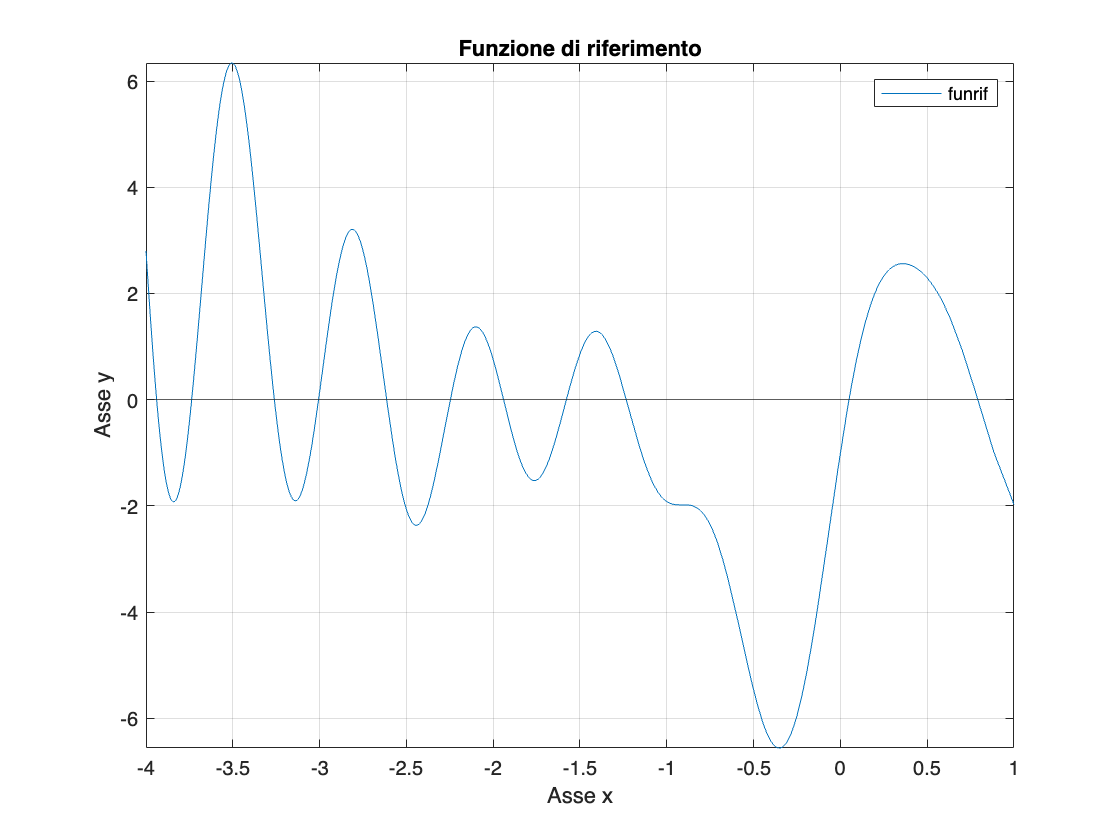

format long %imposto tutti i valori in formato long
figure(1)
%Visualizzo la mia funzione in un intervallo abbastanza ampio per determinare l'intervallo che mi interessa.
fplot(funrif,[-4,1])
hold on
grid on
yline(0) %Evidenzio l'asse delle x

xlabel("Asse x",'FontName','Helvetica')
ylabel("Asse y",'FontName','Helvetica')
title("Funzione di riferimento",'FontName','Helvetica')
legend('funrif')

**Punto 2: visualizzate il grafico della funzione di riferimento in **$[a,b]$**, specificando espicitamente quale intervallo avete scelto, per esempio utilizzando un tratto più spesso rispetto a quello dell'asse x (che deve essere esplicitamente visualizzato con una linea nera; usate i comandi **`title`** e **`legend`** per rendere più leggibile la figura;**

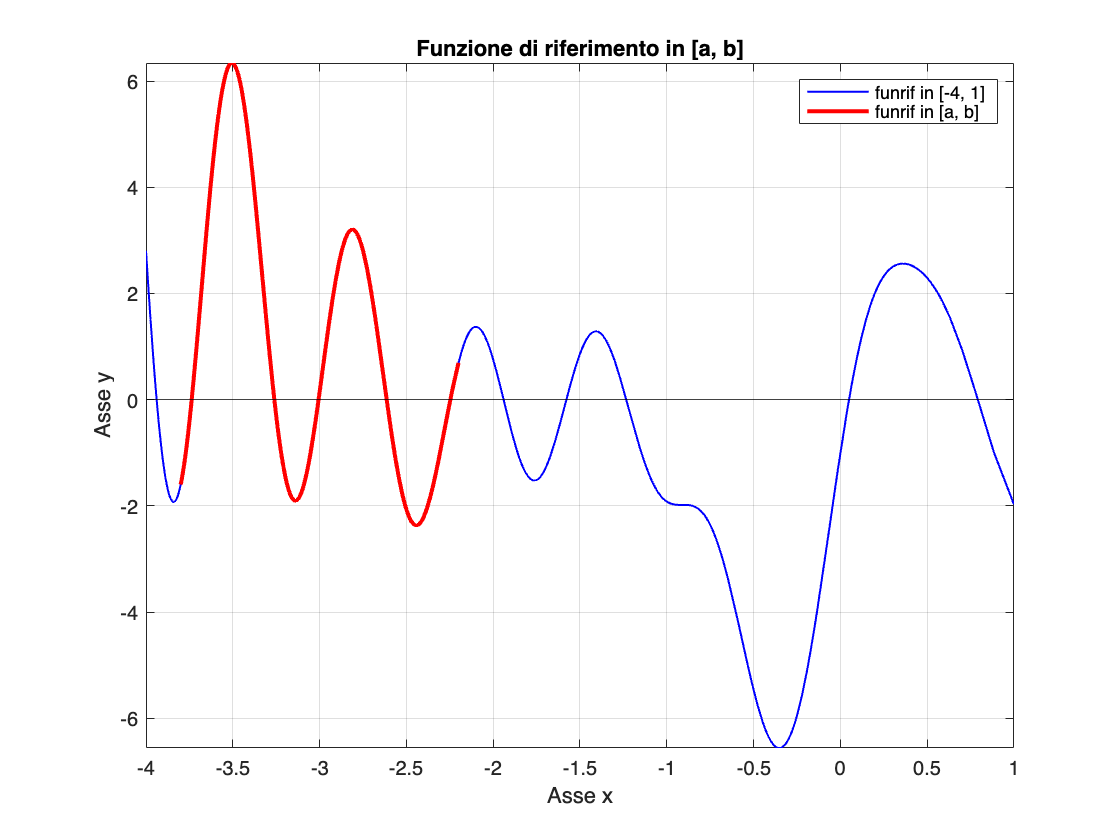

% Definisco l'intervallo [a, b]
a = -3.8;
b = -2.2;

figure(2)
% Visualizzo la mia funzione in un intervallo più ampio con un tratto più sottile e colore blu
fplot(funrif, [-4, 1], 'LineWidth', 1, 'Color', 'b') 
hold on
% Visualizzo la mia funzione nel mio intervallo scelto con un tratto più spesso e colore rosso
fplot(funrif, [a, b], 'LineWidth', 2, 'Color', 'r') 
grid on
% Evidenzio l'asse delle x con una linea nera
yline(0, 'k') 

% Imposto le etichette degli assi e il titolo
xlabel("Asse x",'FontName','Helvetica')
ylabel("Asse y",'FontName','Helvetica')
title("Funzione di riferimento in [a, b]",'FontName','Helvetica')

% Aggiungo la legenda
legend('funrif in [-4, 1]', 'funrif in [a, b]')

**Punto 3: usate la function Matlab **`fzero`** per determinare i 5 zeri della vostra funzione di riferimento in **$[a,b]$**, e considerate i valori calcolati da **`fzero`** come le soluzioni esatte; **

ZeroEsatto=[0 0 0 0 0]; %Creo l'array dove memorizzerò gli zeri esatti
ZeroApprossimato=[-3.6 -3.2 -3 -2.6 -2.3]; %Creo l'array degli zeri approssimativi

%inizio un ciclo for che ad ogni iterazione salverà gli zeri esatti nell'array ZeroEsatto
for i=1:5
    ZeroEsatto(i)=fzero(funrif,ZeroApprossimato(i));
    fprintf('Zero esatto %d = %.15f\n',i,ZeroEsatto(i))
end

Zero esatto 1 = -3.736769600148430
Zero esatto 2 = -3.260688817529754
Zero esatto 3 = -3.005922405748049
Zero esatto 4 = -2.613646885711357
Zero esatto 5 = -2.246944520521285


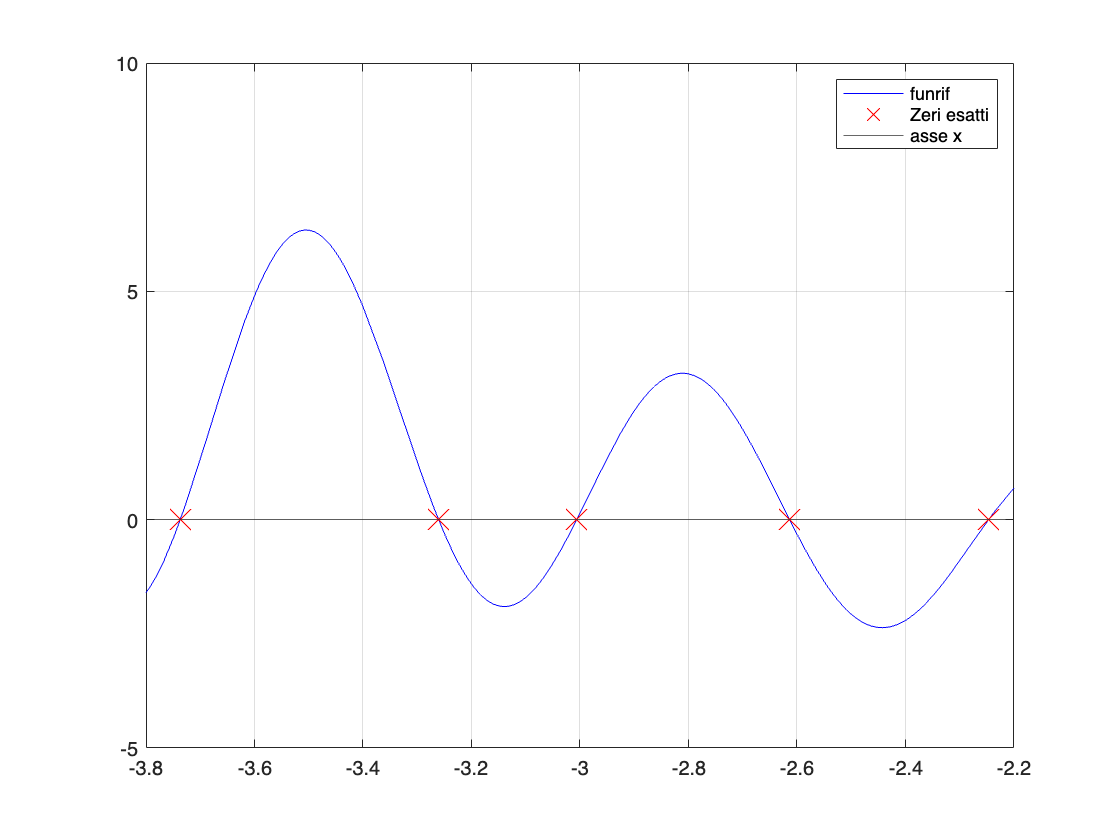

figure(3);
fplot(funrif,[a,b],'color','b')
axis([a b -5 10])

hold on
grid on
yline(0);
%evidenzio sul grafico gli zeri esatti
for i=1:5
    plot((ZeroEsatto(i)),(0),'x','markersize',15,'color','r')
end
legend({'funrif','asse x','Zeri esatti'})

**Punto 4: indicate sul grafico (comando **`text`**) con un pallino rosso i 5 zeri, il primo valore minimo e l'ascissa del primo minimo (detta *****punto di minimo 1*****) entrambi con un triangolino down blu, il secondo valore minimo e l'ascissa del secondo minimo (detta *****punto di minimo 2*****) entrambi con un triangolino down verde, il primo valore massimo e l'ascissa del primo massimo (detta *****punto di massimo 1*****) entrambi con un triangolino up blu, il secondo valore massimo e l'ascissa del secondo massimo (detta *****punto di massimo 2*****) entrambi con un triangolino up verde; usate i comandi **`title`** e **`legend`** per rendere più leggibile la figura;**

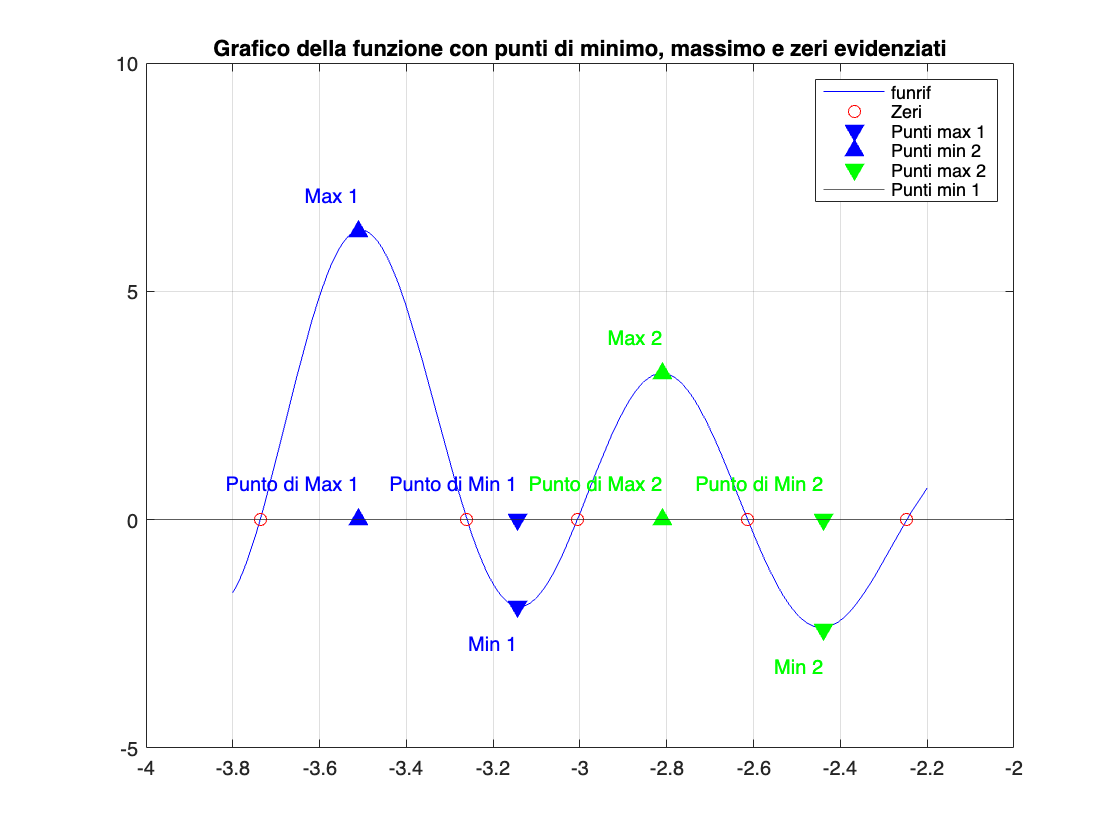

max1 = 6.3; max1_x = -3.51;
max2 = 3.2; max2_x = -2.81;
min1 = -1.9; min1_x = -3.145;
min2 = -2.41; min2_x = -2.44; 

figure(4)
fplot(funrif, [a, b], 'color', 'b') 
hold on 
grid on
axis([-4, -2, -5, 10])
plot(ZeroEsatto, zeros(1, 5), 'o', 'markersize', 6, 'Color', 'r');
yline(0);

% Evidenzio i punti di minimo e di massimo come definito nella traccia
plot(min1_x, min1, 'v', 'markersize', 8, 'color', 'b', 'MarkerFaceColor', 'b');
plot(max1_x, max1, '^', 'markersize', 8, 'color', 'b', 'MarkerFaceColor', 'b');
plot(min2_x, min2, 'v', 'markersize', 8, 'color', 'g', 'MarkerFaceColor', 'g');
plot(max2_x, max2, '^', 'markersize', 8, 'color', 'g', 'MarkerFaceColor', 'g');
plot(min1_x, 0, 'v', 'markersize', 8, 'color', 'b', 'MarkerFaceColor', 'b');
plot(max1_x, 0, '^', 'markersize', 8, 'color', 'b', 'MarkerFaceColor', 'b');
plot(min2_x, 0, 'v', 'markersize', 8, 'color', 'g', 'MarkerFaceColor', 'g');
plot(max2_x, 0, '^', 'markersize', 8, 'color', 'g', 'MarkerFaceColor', 'g');
text(min1_x, min1 - 0.8, 'Min 1', 'color', 'b', 'HorizontalAlignment', 'right');
text(max1_x, max1 + 0.8, 'Max 1', 'color', 'b', 'HorizontalAlignment', 'right');
text(min2_x, min2 - 0.8, 'Min 2', 'color', 'g', 'HorizontalAlignment', 'right');
text(max2_x, max2 + 0.8, 'Max 2', 'color', 'g', 'HorizontalAlignment', 'right');
text(min1_x,  0.8, 'Punto di Min 1', 'color', 'b', 'HorizontalAlignment', 'right');
text(max1_x,  0.8, 'Punto di Max 1', 'color', 'b', 'HorizontalAlignment', 'right');
text(min2_x,  0.8, 'Punto di Min 2', 'color', 'g', 'HorizontalAlignment', 'right');
text(max2_x,  0.8, 'Punto di Max 2', 'color', 'g', 'HorizontalAlignment', 'right');

legend('funrif', 'Zeri', 'Punti min 1', 'Punti max 1', 'Punti min 2', 'Punti max 2');
title('Grafico della funzione con punti di minimo, massimo e zeri evidenziati');

**Punto 5: determinate un'approssimazione dei 5 zeri, usando il metodo Newton (nostra function **`Newton`**) per lo zero più a sinistra (primo zero) e per il secondo zero, il metodo di bisezione (nostra function **`bisezione`**) per il terzo  e quarto zero e il metodo delle Secanti (nostra function **`Secanti`**) per il quinto zero (consiglio: usare **`funtool`** oppure (meglio) il toolbox simbolico (comandi **`syms`** , **`diff `**e**` matlabFunction`**) per determinare l'espressione della derivata della funzione di riferimento), con un valore di **`delta_ass`** che garantisca, in tutti e 5 i casi, che la parte intera e le prime 6 cifre frazionarie siano corrette;**

% Definizione della variabile simbolica
syms x
% Calcolo della derivata della funzione
derivataprima = diff(funrif, x);
derivataprima = matlabFunction(derivataprima);
% Definizione del delta_ass
delta_ass=1e-6;

% Definizione del numero massimo di iterazioni
kmax = 10;

% Metodo di Newton per il primo e secondo zero
zNewton1 = Newton(funrif,derivataprima,-3.73676960,delta_ass,kmax)

zNewton1 =   -3.736769600000000


zNewton2 = Newton(funrif,derivataprima,-3.260688817,delta_ass,kmax)

zNewton2 =   -3.260688817000000



% Metodo di bisezione per il terzo e quarto zero
zBisezione1 = bisezione(funrif,-3.00592240,-3.00592241,delta_ass)

zBisezione1 =   -3.005922405000000


zBisezione2 = bisezione(funrif,-2.61364688,-2.61364689,delta_ass)

zBisezione2 =   -2.613646885000000



% Metodo delle Secanti per il quinto zero
zSecanti = Secanti(funrif,-2.246944520,-2.246944521,delta_ass,kmax)

zSecanti =   -2.246944520000000


**Punto 6: considerate sia l'errore assoluto tra l'approssimazione di **`Newton`** e la corrispondente soluzione esatta (per entrambi gli zeri calcolati con **`Newton`**), sia l'errore assoluto tra l'approssimazione della **`bisezione`** e la corrispondente soluzione esatta (per entrambi gli zeri calcolati con **`bisezione`**), sia l'errore assoluto tra l'approssimazione di **`Secanti `**e la corrispondente soluzione esatta, e verificate che siano minori dell'accuratezza richiesta (**`delta_ass`**), commentando il loro valore; calcolate anche il residuo per ognuna delle cinque approssimazioni e commentate i valori del residuo confrontandoli con quelli del corrispondente errore assoluto  e con l'accuratezza richiesta; solo guardando il grafico della funzione di riferimento, scrivere se, per ognuno dei cinque zeri, il problema appare bene o mal condizionato, spiegando qual è il significato di problema ben/mal condizionato;**

% Calcolo degli errori assoluti
errAssolutoNewton1 = abs(zNewton1 - ZeroEsatto(1))

errAssolutoNewton1 =      1.484301570542357e-10


errAssolutoNewton2 = abs(zNewton2 - ZeroEsatto(2))

errAssolutoNewton2 =      5.297540184301397e-10


errAssolutoBisezione1 = abs(zBisezione1 - ZeroEsatto(3))

errAssolutoBisezione1 =      7.480491781564069e-10


errAssolutoBisezione2 = abs(zBisezione2 - ZeroEsatto(4))

errAssolutoBisezione2 =      7.113571953709652e-10


errAssolutoSecanti = abs(zSecanti - ZeroEsatto(5))

errAssolutoSecanti =      5.212847931090892e-10


Gli errori assoluti calcolati sono tutti inferiori a delta_ass, il che indica che le approssimazioni ottenute con i metodi di Newton, bisezione e secanti sono accurate al livello desiderato.

% Verifica che gli errori assoluti siano inferiori a delta_ass
checkNewton1 = errAssolutoNewton1 < delta_ass

checkNewton1 = logical
   1


checkNewton2 = errAssolutoNewton2 < delta_ass

checkNewton2 = logical
   1


checkBisezione1 = errAssolutoBisezione1 < delta_ass

checkBisezione1 = logical
   1


checkBisezione2 = errAssolutoBisezione2 < delta_ass

checkBisezione2 = logical
   1


checkSecanti = errAssolutoSecanti < delta_ass

checkSecanti = logical
   1



% Calcolo dei residui
residuoNewton1 = abs(funrif(zNewton1))

residuoNewton1 =      4.920445384470895e-09


residuoNewton2 = abs(funrif(zNewton2))

residuoNewton2 =      1.558689177727501e-08


residuoBisezione1 = abs(funrif(zBisezione1))

residuoBisezione1 =      1.772102709018952e-08


residuoBisezione2 = abs(funrif(zBisezione2))

residuoBisezione2 =      1.674360605719016e-08


residuoSecanti = abs(funrif(zSecanti))

residuoSecanti =      8.510085969248848e-09


L'ordine di grandezza dei residui sono superiori a quello dell'accuratezza richiesta, quindi i problemi risultano ben condizionati.


% Calcolo degli indici di condizionamento
indiceCondizionamentoNewton1 = 1/abs(derivataprima(ZeroEsatto(1)))

indiceCondizionamentoNewton1 =    0.030165964272090


indiceCondizionamentoNewton2 = 1/abs(derivataprima(ZeroEsatto(2)))

indiceCondizionamentoNewton2 =    0.033987138778978


indiceCondizionamentoBisezione1 = 1/abs(derivataprima(ZeroEsatto(3)))

indiceCondizionamentoBisezione1 =    0.042212532479424


indiceCondizionamentoBisezione2 = 1/abs(derivataprima(ZeroEsatto(4)))

indiceCondizionamentoBisezione2 =    0.042485305874939


indiceCondizionamentoSecanti = 1/abs(derivataprima(ZeroEsatto(5)))

indiceCondizionamentoSecanti =    0.061254926067897


Guardando il grafico si nota che la funzione non risulta schiacciata quando interseca l'asse delle x, quindi il problema della ricerca dello zero della funrif risulta ben condizionato, un ulteriore conferma è data dai bassi valori degli indici di condizionamento.

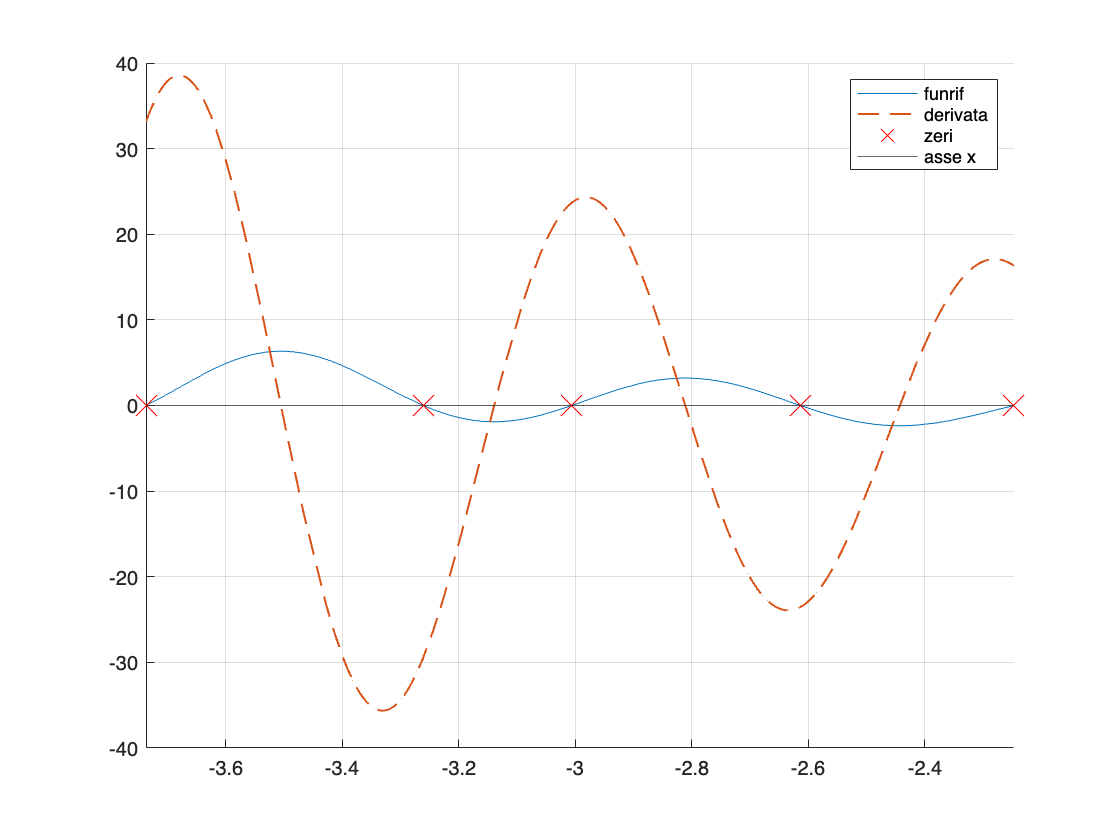

% Visualizzazione del grafico della funzione e della sua derivata
figure(5)
hold on
grid on
fplot(funrif, [min(ZeroEsatto), max(ZeroEsatto)])
fplot(derivataprima, [min(ZeroEsatto), max(ZeroEsatto)], '--', 'LineWidth', 1)
axis([min(ZeroEsatto) max(ZeroEsatto) -40 40])
yline(0)
for i = 1:5
    plot(ZeroEsatto(i), 0, 'x', 'markersize', 15, 'color', 'r')
end
legend('funrif', 'derivata', 'asse x', 'zeri')

**Punto 7:osservando il grafico della vostra funzione di riferimento nell'intervallo **$[a,b]$**e della bisettrice del primo quadrante, stabilite se ci sono punti fissi e determinate il loro numero; poi, senza usare la function **`PFisso (`**suggerimento: trasformate il problema di punto fisso in un problema equivalente di risoluzione di una equazione e usate opportunamente**` fzero)`**, calcolate una approssimazione dei due punti fissi più vicini all'estremo sinistro dell'intervallo, cioè più vicini ad **$a$**, visualizzateli sul grafico con  un quadrato nero e determinate i loro residui; dite se il metodo del punto fisso convergerebbe a tali punti fissi. Solo per i punti fissi per cui la teoria assicuri la convergenza (**`suggerimento: `**calcolate e visualizzate la derivata della funzione di riferimento nei due punti fissi considerati), calcolate tali punti fissi anche con la nostra function **`PFisso`**; commentate i risultati; usate i comandi **`title`** e **`legend`** per rendere più leggibile la figura;**

% Utilizzaremo il nuovo intervallo [a, c] per questo punto, questo perchè nell'intervallo [a,b]
% la bisettrice e la funrif non intersecavano
c = 0.5;

% Mostriamo il grafico con la bisettrice
figure(6)
fplot(funrif,[a,c])
axis([a c -5 10]) 
hold on 
grid on 
bisettrice=linspace (a,c,2);
plot(bisettrice,bisettrice)
title('Grafico della funzione di riferimento e della bisettrice')

% Calcoliamo una approssimazione dei due punti fissi più vicini all'estremo sinistro dell'intervallo
approssimazionePfisso1 = fzero(@(x)funrif(x)-x,-1.2)

approssimazionePfisso1 =   -1.133148727244716


approssimazionePfisso2 = fzero(@(x)funrif(x)-x,0.1)

approssimazionePfisso2 =    0.052313454518643


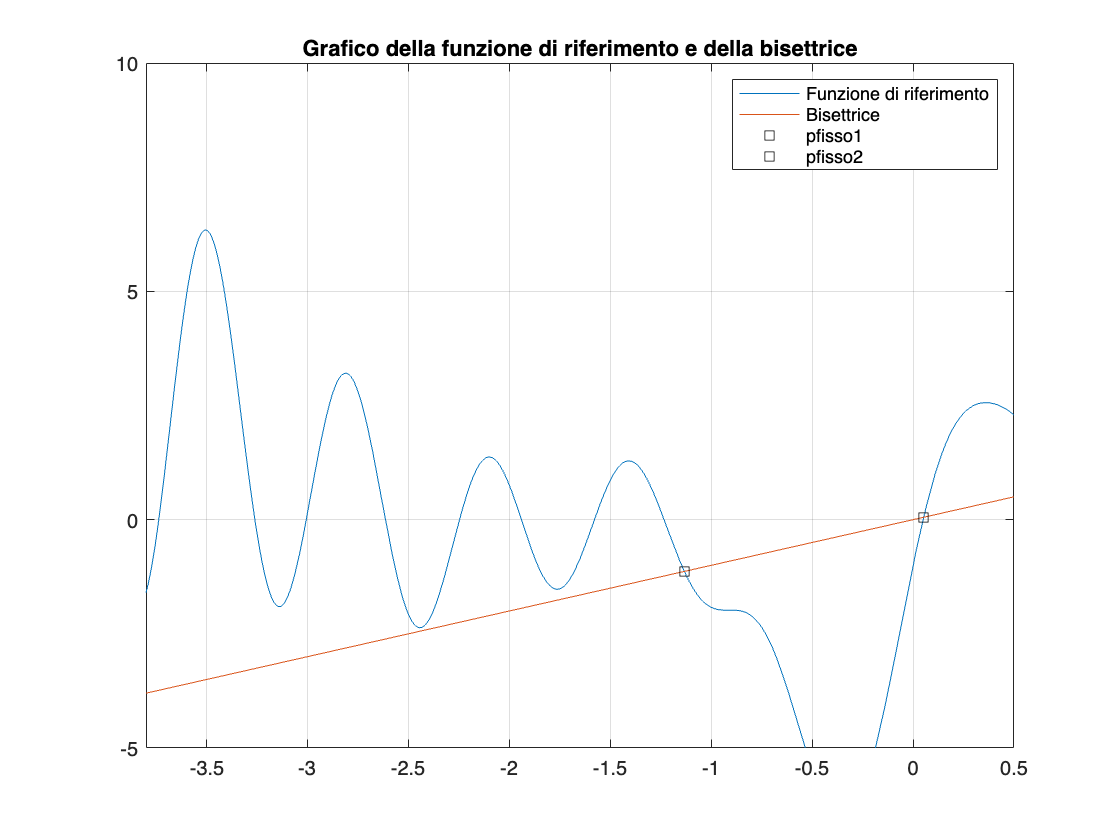


% Visualizziamo i punti fissi sul grafico
plot(approssimazionePfisso1, funrif(approssimazionePfisso1), 'ks')
plot(approssimazionePfisso2, funrif(approssimazionePfisso2), 'ks')
legend('Funzione di riferimento', 'Bisettrice', 'pfisso1', 'pfisso2')



% Calcoliamo i residui
residuoPfisso1 = abs(funrif(approssimazionePfisso1)-approssimazionePfisso1)

residuoPfisso1 =      0


residuoPfisso2 = abs(funrif(approssimazionePfisso2)-approssimazionePfisso2)

residuoPfisso2 =      1.387778780781446e-16



% Calcoliamo il valore della derivata nei punti fissi
derivataPuntoFisso1 = derivataprima(approssimazionePfisso1);
derivataPuntoFisso2 = derivataprima(approssimazionePfisso2);

% Verifichiamo se il metodo del punto fisso convergerebbe a tali punti fissi
if abs(derivataPuntoFisso1) < 1
    disp('Il metodo del punto fisso convergerebbe al primo punto fisso.')
else
    disp('Il metodo del punto fisso non convergerebbe al primo punto fisso.')
end

Il metodo del punto fisso non convergerebbe al primo punto fisso.



if abs(derivataPuntoFisso2) < 1
    disp('Il metodo del punto fisso convergerebbe al secondo punto fisso.')
else
    disp('Il metodo del punto fisso non convergerebbe al secondo punto fisso.')
end

Il metodo del punto fisso non convergerebbe al secondo punto fisso.


Siccome in entrambi casi abbiamo risultato negativo sarebbe inutile utilizzare la function PFisso

**Punto 8: usate la function Matlab **`fminbnd`** per determinare i due punti di minimo e i due punti di massimo della vostra funzione di riferimento in **$[a,b]$**, con quattro chiamate del tipo: **`fminbnd(fun,sinistro,destro,optimset('TolX',1e-10))`**, e considerate i valori calcolati da **`fminbnd`** come le soluzioni esatte (cioè come valori esatti dei due punti di minimo e dei due punti di massimo). Visualizzate sul grafico sia i punti di minimo e massimo, sia i valori minimi e massimi ivi assunti dalla funzione di riferimento;**

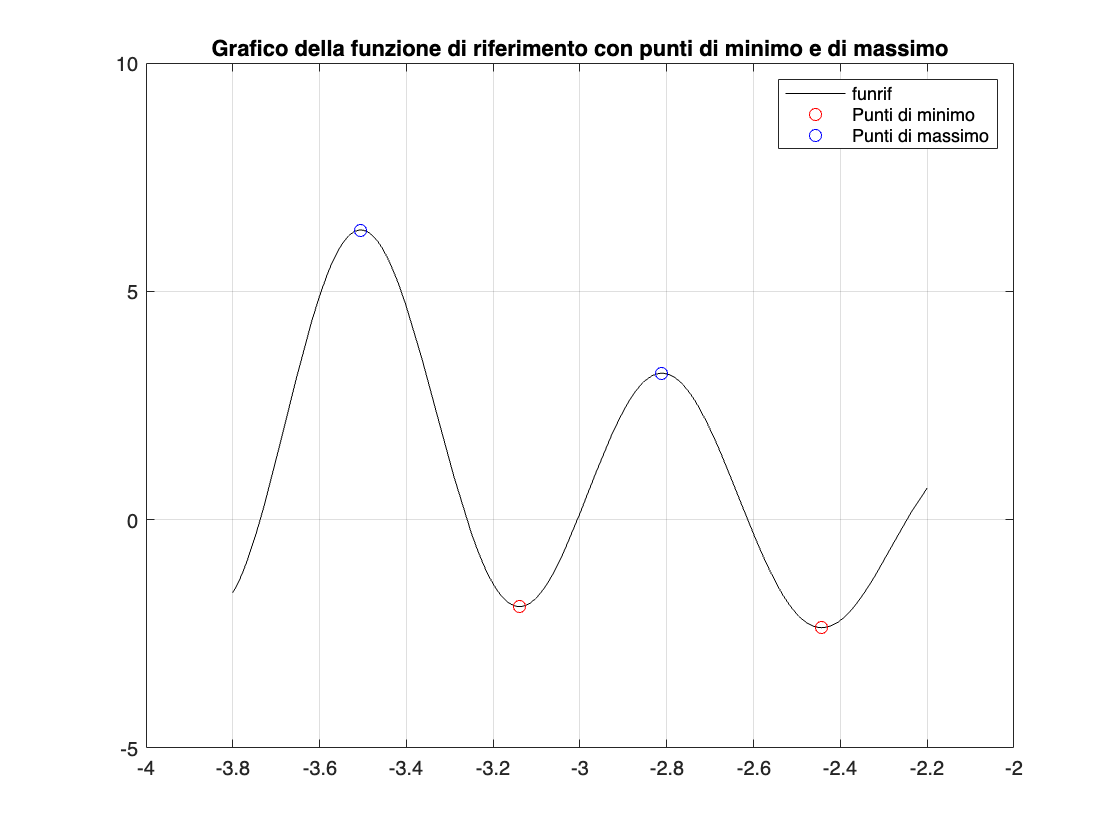

% Calcolo dei punti di minimo
min1_x = fminbnd(funrif,-3.2,-3.1,optimset('TolX',1e-10));
min2_x = fminbnd(funrif,-2.5,-2.4,optimset('TolX',1e-10));

% Definizione della funzione inversa
funrifInversa = @(x) -funrif(x);

% Calcolo dei punti di massimo
max1_x = fminbnd(funrifInversa,-3.6,-3.5,optimset('TolX',1e-10));
max2_x = fminbnd(funrifInversa,-2.9,-2.8,optimset('TolX',1e-10));

% Calcolo dei valori di minimo e massimo
min1 = funrif(min1_x);
min2 = funrif(min2_x);
max1 = funrif(max1_x);
max2 = funrif(max2_x);

% Visualizzazione dei risultati
figure(7)
fplot(funrif, [a, b], 'color', 'k') 
hold on 
grid on

axis([-4, -2, -5, 10])
plot([min1_x, min2_x], [min1, min2], 'ro')
plot([max1_x, max2_x], [max1, max2], 'bo')
title('Grafico della funzione di riferimento con punti di minimo e di massimo')
legend('funrif', 'Punti di minimo', 'Punti di massimo')
hold off

**Punto 9: verificate che i due punti di minimo e i due punti di massimo sono zeri della derivata della vostra funzione di riferimento (consiglio: usare **`funtool`** o (meglio)  il toolbox simbolico (comandi **`syms`** , **`diff `**e**` matlabFunction`**) per determinare l'espressione della derivata della funzione di riferimento), visualizzando nella stessa figura sia il grafico della funzione (in blu) sia il grafico della sua derivata (in rosso) [può essere utile usare anche la scalatura verticale della finestra grafica data dal comando **`ylim([ymin, ymax])`** ], e usando la **`fzero`** per calcolare tutti gli zeri della derivata nell'intervallo **$[a,b]$**; commentate i risultati ottenuti; usate i comandi **`title`** e **`legend`** per rendere più leggibile la figura;**

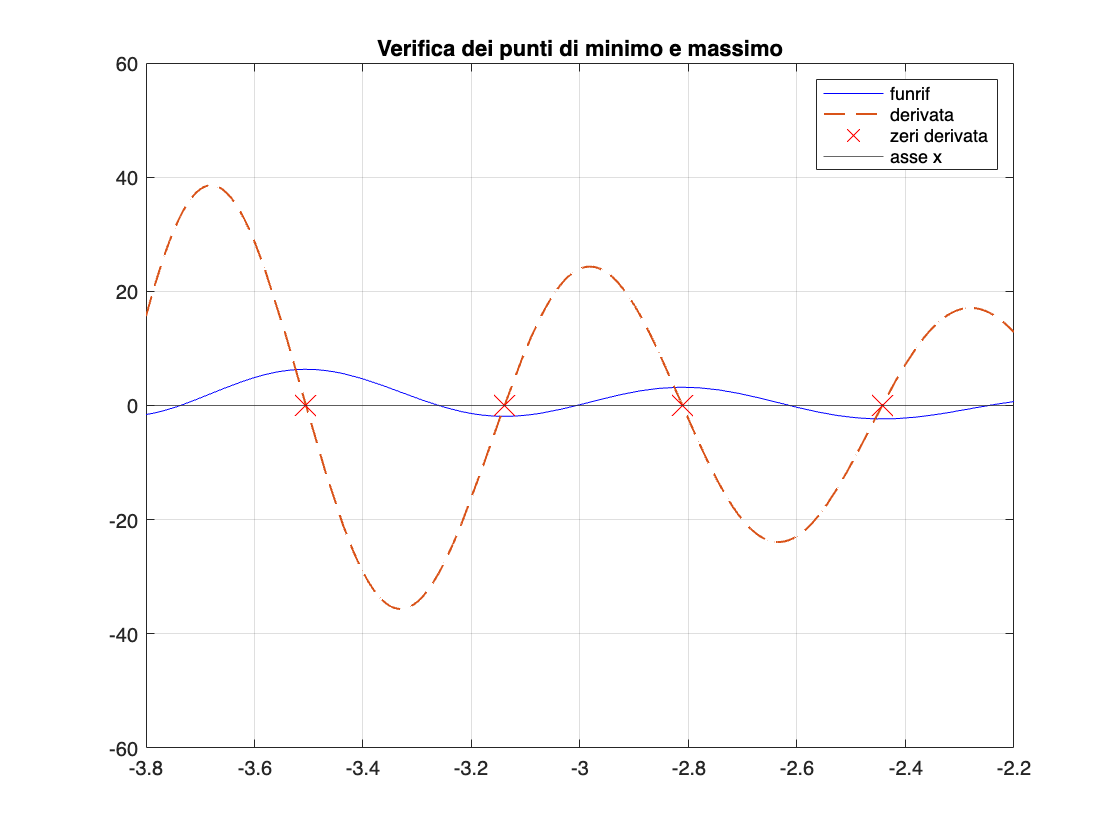

% Calcolo degli zeri della derivata
zDerivata1 = fzero(derivataprima, min1_x);
zDerivata2 = fzero(derivataprima, min2_x);
zDerivata3 = fzero(derivataprima, max1_x);
zDerivata4 = fzero(derivataprima, max2_x);
% Dal grafico possiamo verificare che i punti di minimo e di massimo sono
% zeri della derivata della funrif
figure(8)
fplot(funrif, [a, b], 'color', 'b') 
hold on 
grid on
axis([-3.8, -2.2, -5, 10])
fplot(derivataprima,[-4,0],'--','LineWidth',1)
plot([zDerivata1 zDerivata2 zDerivata3 zDerivata4],[0 0 0 0],'x','markersize',15,'color','r');
ylim([-60 60])
yline(0)
legend('funrif','derivata','zeri derivata','asse x')
title('Verifica dei punti di minimo e massimo')
hold off

**Punto 10: determinate un'approssimazione dei due punti di minimo e dei due punti di massimo, usando, rispettivamente, due volte il metodo di Fibonacci search (nostra function **`fminfibo`**) per i due minimi, e il metodo di Golden search (nostra function **`fmingolden`**) per i due massimi, con un valore di **`delta_ass`** che garantisca che la parte intera e le prime 3 cifre frazionarie siano corrette; **

% Definizione del valore di delta_ass
delta_ass2 = 1e-3;

% Calcolo dei punti di minimo con il metodo di Fibonacci search
min1_fx = fminfibo(funrif, -3.2, -3.1, delta_ass2)

min1_fx =   -3.140000000000000


min2_fx = fminfibo(funrif, -2.5, -2.4, delta_ass2)

min2_fx =   -2.443636363636363



% Calcolo dei punti di massimo con il metodo di Golden search
max1_gx = fmingolden(funrifInversa, -3.6, -3.5, delta_ass2)

max1_gx =   -3.505166278062295


max2_gx = fmingolden(funrifInversa, -2.9, -2.8, delta_ass2)

max2_gx =   -2.811241586936443


**Punto 11: considerate l'errore assoluto tra le due approssimazioni ottenute dalle due chiamate alla Golden search e le due corrispondenti soluzioni esatte e poi l'errore assoluto tra le due approssimazioni ottenute dalle due chiamate alla Fibonacci search e le due corrispondenti soluzioni esatte, e verificate che siano in tutti e quattro i casi minori dell'accuratezza richiesta (**`delta_ass`**), commentando i risultati.**

errAssolutoGolden1 = abs(max1_gx-max1_x)

errAssolutoGolden1 =      5.253407588190484e-05


errAssolutoGolden2 = abs(max2_gx-max2_x)

errAssolutoGolden2 =      4.903654059074114e-05


errAssolutoFibonacci1 = abs(min1_fx-min1_x)

errAssolutoFibonacci1 =      6.304107637262746e-04


errAssolutoFibonacci2 = abs(min2_fx-min2_x)

errAssolutoFibonacci2 =      6.054578872216609e-04


errAssolutoGolden1<delta_ass2

ans = logical
   1


errAssolutoGolden2<delta_ass2

ans = logical
   1


errAssolutoFibonacci1<delta_ass2

ans = logical
   1


errAssolutoFibonacci2<delta_ass2

ans = logical
   1


In tutti e quattro i casi i valori dell'errore assoluto risultano inferiori all'accuratezza richiesta.